## Construction of phasor Array

## Intro

The phasorArray class is a usefull tool to manipulate 3D array representing Periodic matrix, storing complex phasor along the third dimension. Obligatory, third dimension must me an odd number. 

Let's use the class PhasorArray to attach usefull function to a 3D matrix representing a periodic matrix and its phasor.

Consider A a 3D array of size $2h+1$ , A(:,:,h+1) is the 0-phasor of A, $A(:,:,(h+1)-m)$ and $A(:,:,(h+1)+m)$ are the $-m$ and $m$ phaors of A. 

The class allow construction, manipulation, edition of phasor in a smooth manner, and redifine all the basic operation (addition, substraction, multiplication, left/right inversion, transposition, conj transpore, real, imag ....) to apply to the periodic matrix instead of the array operation. 

### Construting a phasorArray

A_0=eye(2);
A_1=[1 1i;-1i,2];
A_2=[2*1i, exp(1i*1.89)/4; 0.5, -1];

A_ar=cat(3,conj(A_2),conj(A_1),A_0,A_1,A_2);
A=PhasorArray(A_ar)

A =   2×2×5 PhasorArray array with properties:

    Phasor3D: [2×2×5 double]


Alternatively, specify that A represent a real valued periodic matrix, ie negative phasor are the conjugate of positive phasor, and feed the function only with the Zero and Positive part, and speficify the argument 'isreal' to true

A_arpos=cat(3,A_0,A_1,A_2);
A=PhasorArray(A_arpos,'isreal',true)

A =   2×2×5 PhasorArray array with properties:

    Phasor3D: [2×2×5 double]


The last way to construct PhasorArray is to specifiy individual periodic coefficient.

For that you can avoid the hassle to construct a 3D matrix, and provide a vector in order to define a scalar periodic PhasorArray. Using this, individual coeef can have different number of phasor but can still concatenate

a_11=ScalarPhasorArray([1,1,2*1i],'isreal',true)

a_11 =   1×1×5 PhasorArray array with properties:

    Phasor3D: [1×1×5 double]


a_12=ScalarPhasorArray([0,1i,exp(1i*1.89)/4, 1/7, 1/8*1i ],'isreal',true)

a_12 =   1×1×9 PhasorArray array with properties:

    Phasor3D: [1×1×9 double]


a_21=ScalarPhasorArray([0,-1i,0.5],'isreal',true)

a_21 =   1×1×5 PhasorArray array with properties:

    Phasor3D: [1×1×5 double]


a_22=ScalarPhasorArray([1,2,-1],'isreal',true)

a_22 =   1×1×5 PhasorArray array with properties:

    Phasor3D: [1×1×5 double]



A=[a_11,a_12;a_21,a_22]

A =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]


### Display phasorArray

%display the 3D array
A.value

ans = ans(:,:,1) =

   0.0000 + 0.0000i   0.0000 - 0.1250i
   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,2) =

   0.0000 + 0.0000i   0.1429 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,3) =

   0.0000 - 2.0000i  -0.0785 - 0.2374i
   0.5000 + 0.0000i  -1.0000 + 0.0000i


ans(:,:,4) =

   1.0000 + 0.0000i   0.0000 - 1.0000i
   0.0000 + 1.0000i   2.0000 + 0.0000i


ans(:,:,5) =

   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i


ans(:,:,6) =

   1.0000 + 0.0000i   0.0000 + 1.0000i
   0.0000 - 1.0000i   2.0000 + 0.0000i


ans(:,:,7) =

   0.0000 + 2.0000i  -0.0785 + 0.2374i
   0.5000 + 0.0000i  -1.0000 + 0.0000i


ans(:,:,8) =

   0.0000 + 0.0000i   0.1429 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,9) =

   0.0000 + 0.0000i   0.0000 + 0.1250i
   0.0000 + 0.0000i   0.0000 + 0.0000i


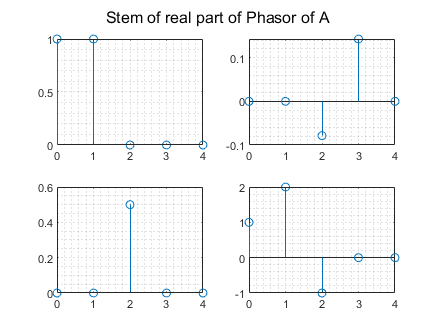


%stem plot
figure
clf
stem(A,display="real",scale="linear")
sgtitle('Stem of real part of Phasor of A')

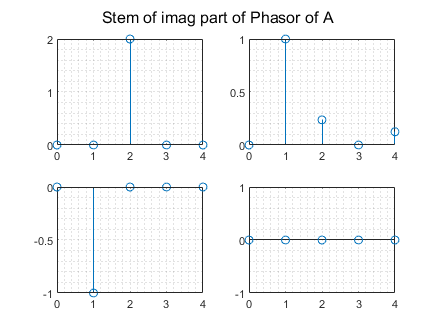


figure
clf
stem(A,display="imag",scale="linear")
sgtitle('Stem of imag part of Phasor of A')

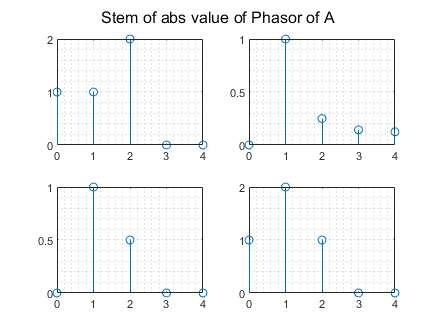


figure
clf
stem(A,display="abs",scale="linear")
sgtitle('Stem of abs value of Phasor of A')

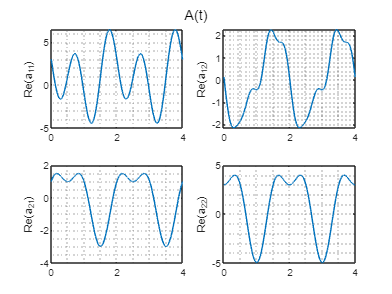


%temporal plot
figure
clf
plot(A,2,0:0.001:4,"title",'A(t)')

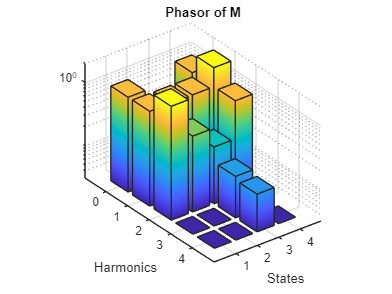


figure
barsurf(A)

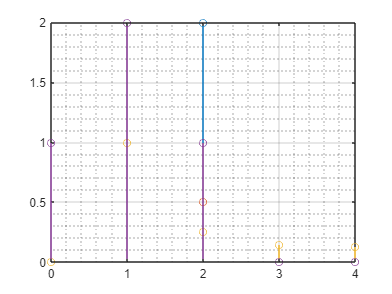


figure
stem(A,"explosed",0,"scale","linear")

### Perform derivation and phase shift

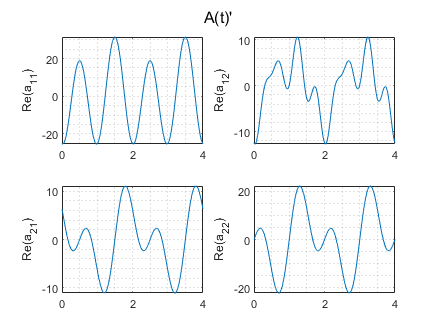

figure
plot(d(A,2),2,0:0.001:4,"title","A(t)'") %derivative of A, for a period T=2

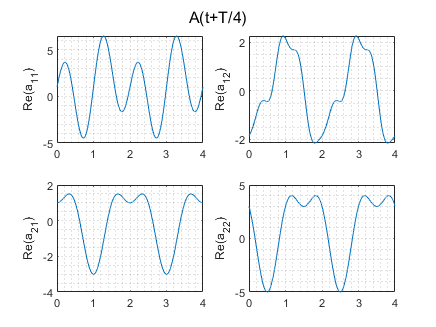


figure
plot(dephase(A,pi/2),2,0:0.001:4,"title","A(t+T/4)") %dephasage de A de pi/2 rad

### Edit PhasorArray

You can modify value of PhasorArray by two means

Access 3D array using parenthesis to manipulate it as a 3D array in regular matlab way

A(1,1,3)=5 % access the third page of 3D array, since A is of size 5,

A =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]


% the 3rd page is the central page,
% so it is the 0 phasor,
%  since we specify (1,1,3) we edit the value of the first coeeficient of
%  A(t)

A(1,1,(A.h+1)+0) = 5 %A.h produces the number of phasor in A

A =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]


% so (A.h+1)+k is the index of the k-th phasor page

Alternatively **use bracket with 2 indices** to access coefficient subphasor array, you can use bracket indexing to totaly replace phasor value of specified coefficients

A{1,1} %extract the phasor Array of (1,1) element of A(t)

ans =   1×1×9 PhasorArray array with properties:

    Phasor3D: [1×1×9 double]


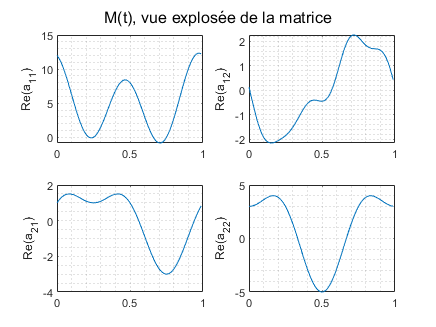

figure
plot(A)

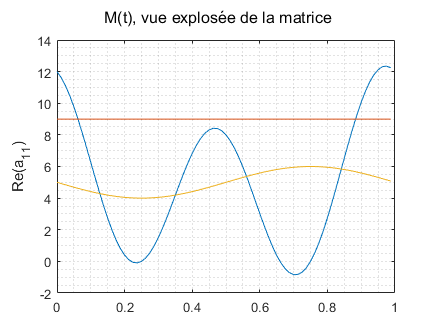


figure
plot(A{1,1})

A{1,1}=9;
hold on
plot(A{1,1})

A{1,1}=ScalarPhasorArray([5 1/2*1i],'isreal',true); %replace a_11 with 5-sin(wt)
hold on
plot(A{1,1})

You can also **use bracket with 3 indices **to assign to specific phasor BUT unlike parenthesis indexing the third argument is a phasor indices 

- A{1,2,3} access the third phasor of $a_{12}$ in the same way A(1,1,3+1+A.h) does

- A{1,1,-3} is a licit indexing

- if k is too big (k > A.h) the output is zero

A{1,1,1}

ans = 0.0000 + 0.5000i

A(1,1,1+1+A.h)

ans = 0.0000 + 0.5000i

A{1,1:2,7}

ans =      0     0


A{:,:,-4}

ans =    0.0000 + 0.0000i   0.0000 - 0.1250i
   0.0000 + 0.0000i   0.0000 + 0.0000i



%change value of phasor -3 of a_11 and a_12
A{1,1:2,-3}=[1/4*1i 1/3+1i/5] 

A =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]


To access full phasor of  order k, an alternative to A{:,:,k} is A.phas(k)

A.phas(-3)

ans =    0.0000 + 0.2500i   0.3333 + 0.2000i
   0.0000 + 0.0000i   0.0000 + 0.0000i


finally use A{:} to extract a vector form of A

A{:}

ans =   4×1×9 PhasorArray array with properties:

    Phasor3D: [4×1×9 double]


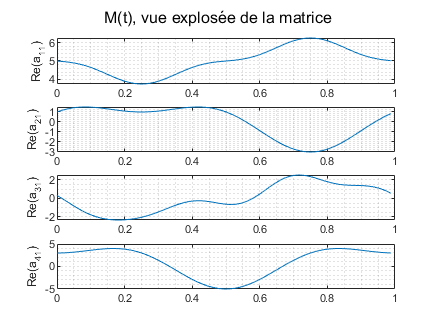

figure
plot(A{:})

Use trunc et reduce pour réduire les phasor Array

E=rand_phasor(2,2,100,'output','PhasorArray')

E =   2×2×201 PhasorArray array with properties:

    Phasor3D: [2×2×201 double]


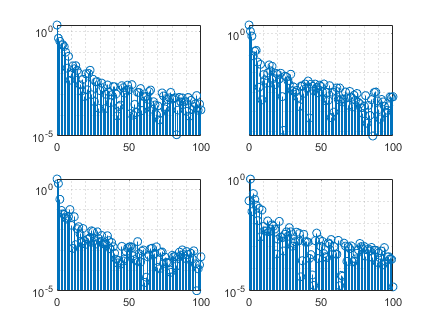

figure
stem(E)

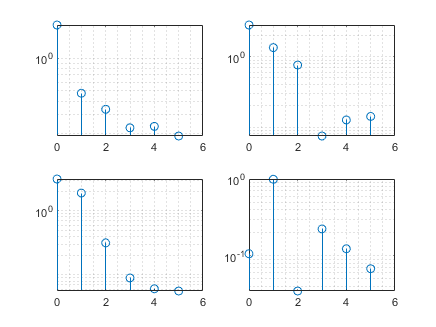


figure
stem(E.trunc(5))

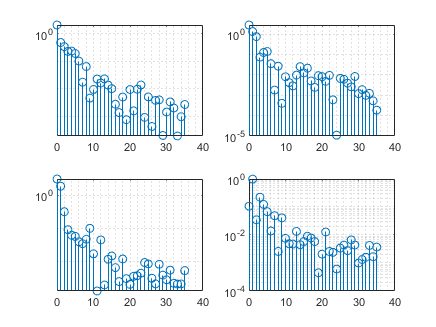


figure
stem(E.reduce([],'method','absolute','threshold',1e-2))

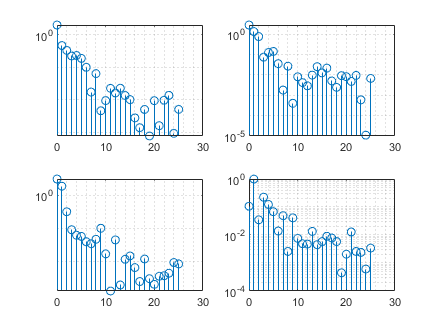

%coupe des que tous les phasors après sont plus petit que 1e-2

figure
stem(E.reduce([],'method','relative','threshold',1e-2))

%coupe des que tous les phasors après sont plus petit que 1e-2 fois le max
%des phasors




### Basic manipulation

We want to manipulate the 3D array (Phasor Array) as is they are matrices. Hence we redefine the + * .* / ./ ' .' operateur to produce result on the periodic matrices. 

A+4 (addition with a scalar) adds 4 only to the 0 phasor, C=A*B realise the product of the periodic matrices st $C(t)=A(t)B(t)$, the is element wise product too : C=A.*B means $c_{kl}(t) = a_{kl}(t) b_{kl}(t)$ and so on for matrix division and element wise division. 

PhasorArray class define the addition in the sens of Matrix : AA=A+4 adds 4 only to the 0 phasor of A 

AA=A+8*eye(2)

AA =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]


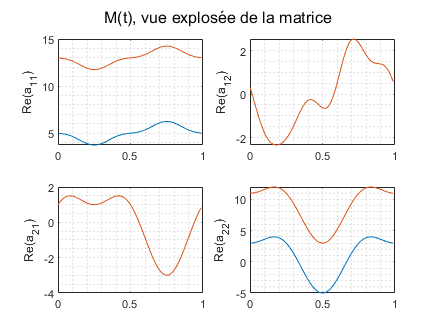

figure
plot(A)
hold on 
plot(AA)

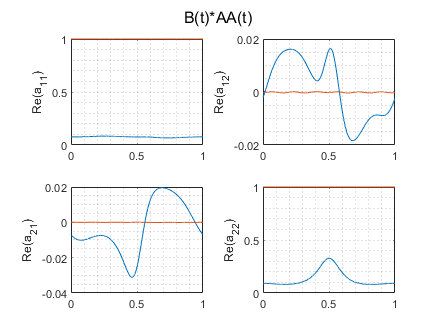



B=1/AA;
figure
plot(B,title='B(t)')
hold on 
plot(B*AA,title='B(t)*AA(t)') 


C=rand_phasor(2,2,5,"output","PhasorArray","time_structure","real")

C =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


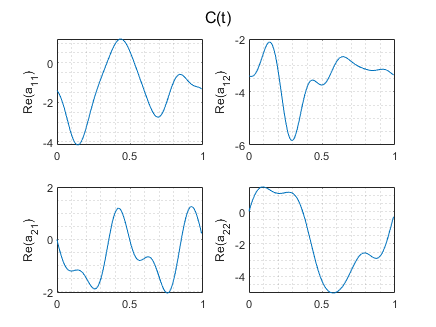

figure
plot(C,title='C(t)')

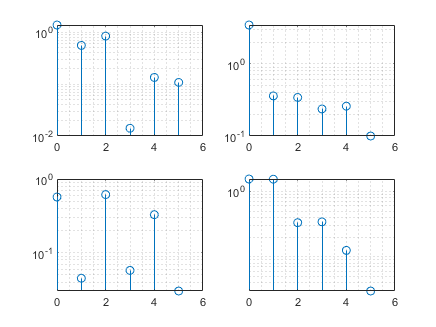

figure
stem(C)

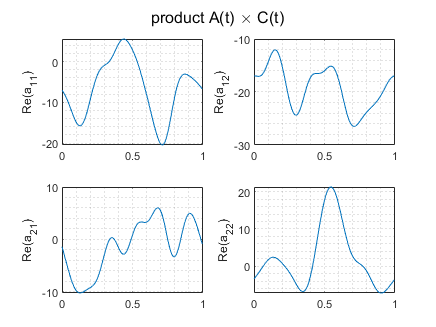

figure
plot(A*C,title='product A(t) \times C(t)')

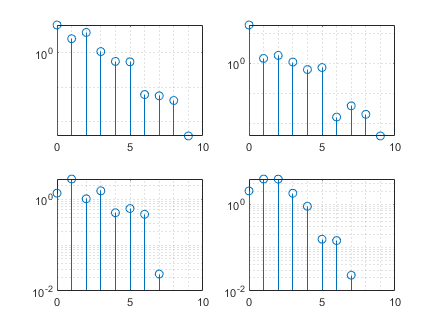



figure(11)
clf
stem(A*C)

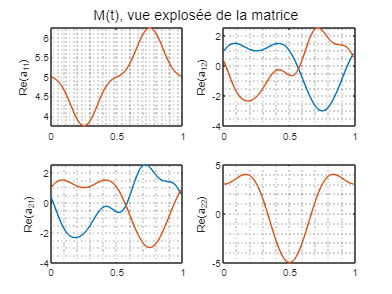

figure
clf
plot(A.') %transpose et complexe transpose fonctionnent
hold on
plot(A)

You can perform smoothly addition and substraction of phasor array containing a different number of phasor as long as the first two dimmension are compatible

D=rand_phasor(2,2,4)

D = D(:,:,1) =

   0.0799 + 0.0128i  -0.1056 + 0.0840i
   0.0348 + 0.0098i   0.0420 - 0.0757i


D(:,:,2) =

  -0.1245 + 0.0012i   0.1491 - 0.1526i
   0.1292 - 0.0635i  -0.0785 - 0.0783i


D(:,:,3) =

  -0.0108 - 0.0835i   0.1956 - 0.0848i
  -0.2131 + 0.1557i   0.3346 - 0.2093i


D(:,:,4) =

   1.0897 + 0.5657i  -0.0662 - 0.2280i
   0.8723 - 0.6813i  -0.1629 - 1.4889i


D(:,:,5) =

   1.3061 + 0.0000i   1.0266 + 0.0000i
  -3.5503 + 0.0000i  -6.6540 + 0.0000i


D(:,:,6) =

   1.0897 - 0.5657i  -0.0662 + 0.2280i
   0.8723 + 0.6813i  -0.1629 + 1.4889i


D(:,:,7) =

  -0.0108 + 0.0835i   0.1956 + 0.0848i
  -0.2131 - 0.1557i   0.3346 + 0.2093i


D(:,:,8) =

  -0.1245 - 0.0012i   0.1491 + 0.1526i
   0.1292 + 0.0635i  -0.0785 + 0.0783i


D(:,:,9) =

   0.0799 - 0.0128i  -0.1056 - 0.0840i
   0.0348 - 0.0098i   0.0420 + 0.0757i


E=A-D

E =   2×2×9 PhasorArray array with properties:

    Phasor3D: [2×2×9 double]



F=kron(A,D)

F =   4×4×17 PhasorArray array with properties:

    Phasor3D: [4×4×17 double]


Basic function such as sum, trace, diag etc are available

diag(A)

ans =   2×1×9 PhasorArray array with properties:

    Phasor3D: [2×1×9 double]


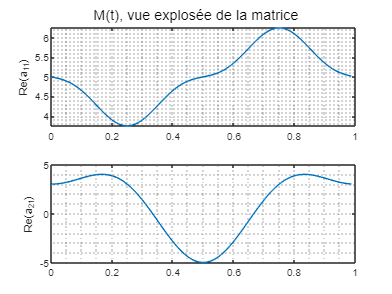

figure
plot(diag(A))


trace(A)

ans =   1×1×9 PhasorArray array with properties:

    Phasor3D: [1×1×9 double]


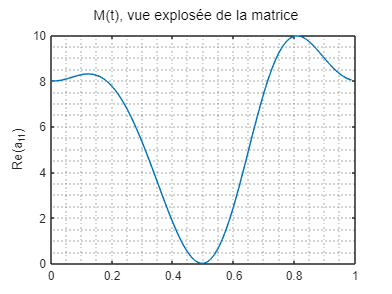

figure
plot(trace(A))

N.B. notice that $trace(\mathcal{T}_m(A))=\frac{trace(A(t)_0)}{2m+1}$

Power are defined

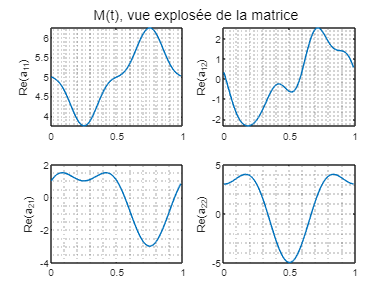

figure
plot(A)

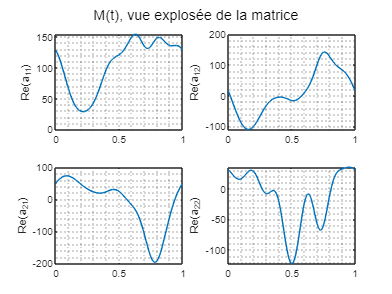

figure
plot(A^3)

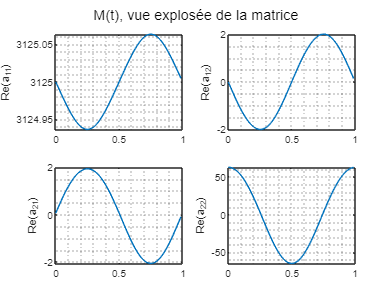

figure
plot(A.^5)

## Simulation of system

Lets take a random periodic matrix with imposed eigen value on S-N

figure
S=mreal(rand_phasor(2,2,7,"hurwitzeig",[-1 -0.3],"time_structure","hurwitz",output="PhasorArray"))

S =   2×2×15 PhasorArray array with properties:

    Phasor3D: [2×2×15 double]



tmax=15;
T=1

T = 1

x0=rand(2,1);
[t,y]=lsim(S,tmax,x0,T,"plot",true,"checkreal",1); 

3848 successful steps
0 failed attempts
4162 function evaluations
1 partial derivatives
310 LU decompositions
4158 solutions of linear systems


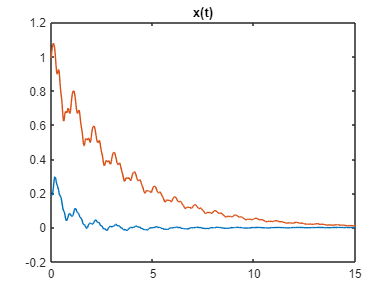

%check real ensure only real value are used, tune this argument to true if
%the periodic matrices are real valued
title('x(t)')

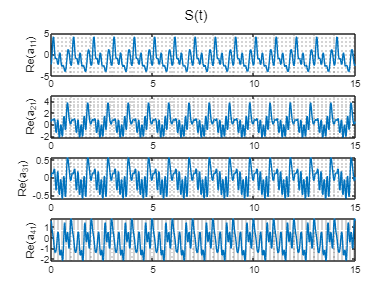


figure
plot(S{:},T,0:0.01:tmax,title='S(t)')

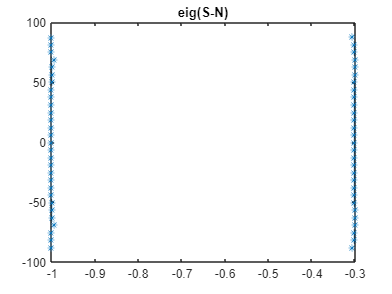


figure
plot(S.HmqNEig([],T),'*')
title('eig(S-N)')

We now add an input to the simulation

B=rand_phasor(2,1,5,"time_structure","real",output="PhasorArray")

B =   2×1×11 PhasorArray array with properties:

    Phasor3D: [2×1×11 double]


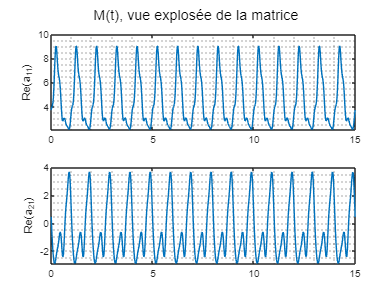

figure
plot(B,T,0:0.01:tmax)


figure
[t,y]=lsim(S,tmax,x0,T,[],B,"plot",true,"checkreal",1);

3948 successful steps
84 failed attempts
4626 function evaluations
1 partial derivatives
420 LU decompositions
4622 solutions of linear systems


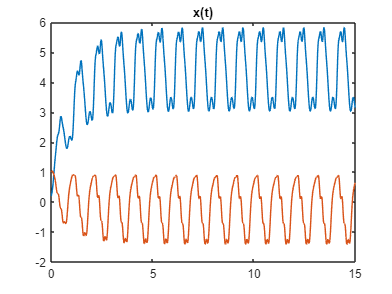

title('x(t)')

## Advanded manipulation

Take a complexe valued phasor array, you can extract the real part of A(t) and imag part of A(t), conjugate phasor, and transpose conjugate phasor with '

X = rand_phasor(2,2,5,"time_structure","cmplx",output="PhasorArray")

X =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


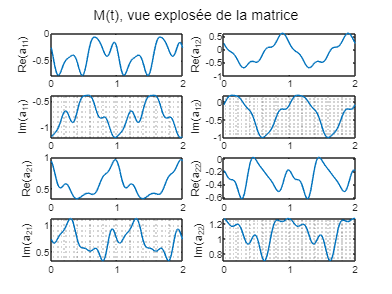

figure
plot(X,1,0:0.01:2,"DispImag",1,"DispReal",1)


rX=mreal(X)

rX =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


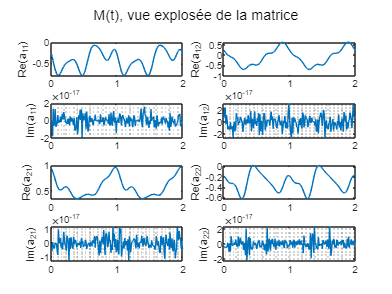

figure
plot(rX,1,0:0.01:2,"DispImag",1,"DispReal",1)


iX=mimag(X)*1i

iX =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


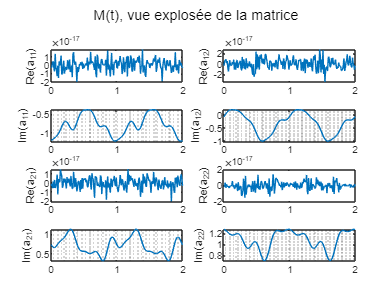

figure
plot(iX,1,0:0.01:2,"DispImag",1,"DispReal",1)


cX=mconj(X)

cX =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


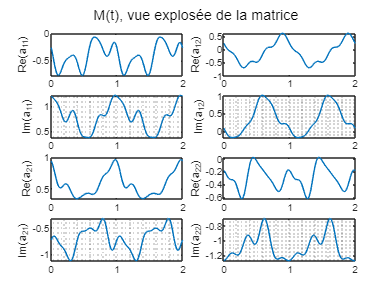

figure
plot(cX,1,0:0.01:2,"DispImag",1,"DispReal",1)


tcX=X'

tcX =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


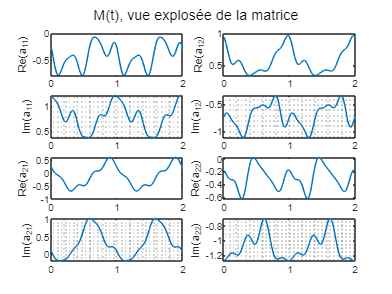

figure
plot(tcX,1,0:0.01:2,"DispImag",1,"DispReal",1)

## Harmonic Array

Construct the Toeplitz Block Form and BlockToeplitz form of order h using the BT and TB method

h=5

h = 5


%TB and BT matrix
A.TB(h)

ans =    5.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.2500i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i  -0.0785 - 0.2374i   0.3333 + 0.2000i   0.0000 - 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   5.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.2500i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i  -0.0785 - 0.2374i   0.3333 + 0.2000i   0.0000 - 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   5.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.2500i   0.0000 + 0.0000i   0.0000 + 0.0000i   0

A.BT(h)

ans =    5.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 - 1.0000i   0.0000 + 0.0000i  -0.0785 - 0.2374i   0.0000 + 0.2500i   0.3333 + 0.2000i   0.0000 + 0.0000i   0.0000 - 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   2.0000 + 0.0000i   0.5000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 1.0000i   5.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 - 1.0000i   0.0000 + 0.0000i  -0.0785 - 0.2374i   0


%en version sparse
A.spBT(h)

ans = NaN

A.spTB(h)

ans =    (1,1)      5.0000 + 0.0000i
   (2,1)      0.0000 + 0.5000i
  (13,1)      0.0000 - 1.0000i
  (14,1)      0.5000 + 0.0000i
   (1,2)      0.0000 - 0.5000i
   (2,2)      5.0000 + 0.0000i
   (3,2)      0.0000 + 0.5000i
  (12,2)      0.0000 + 1.0000i
  (14,2)      0.0000 - 1.0000i
  (15,2)      0.5000 + 0.0000i
   (2,3)      0.0000 - 0.5000i
   (3,3)      5.0000 + 0.0000i
   (4,3)      0.0000 + 0.5000i
  (12,3)      0.5000 + 0.0000i
  (13,3)      0.0000 + 1.0000i
  (15,3)      0.0000 - 1.0000i
  (16,3)      0.5000 + 0.0000i
   (1,4)      0.0000 + 0.2500i
   (3,4)      0.0000 - 0.5000i
   (4,4)      5.0000 + 0.0000i
   (5,4)      0.0000 + 0.5000i
  (13,4)      0.5000 + 0.0000i
  (14,4)      0.0000 + 1.0000i
  (16,4)      0.0000 - 1.0000i
  (17,4)      0.5000 + 0.0000i
   (2,5)      0.0000 + 0.2500i
   (4,5)      0.0000 - 0.5000i
   (5,5)      5.0000 + 0.0000i
   (6,5)      0.0000 + 0.5000i
  (14,5)      0.5000 + 0.0000i
  (15,5)      0.0000 + 1.0000i
  (17,5)      0.0000 - 1.0000i
  


T=1 %period

T = 1

nx=2 %number of state

nx = 2

NTB(nx,h,T)

ans =    0.0000 -31.4159i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -25.1327i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -18.8496i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0

NBT(nx,h,T)

ans =    0.0000 -31.4159i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -25.1327i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -18.8496i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -12.5664i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 6.2832i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  


spNBT(nx,h,T)

ans =    (1,1)      0.0000 -31.4159i
   (2,2)      0.0000 -25.1327i
   (3,3)      0.0000 -18.8496i
   (4,4)      0.0000 -12.5664i
   (5,5)      0.0000 - 6.2832i
   (7,7)      0.0000 + 6.2832i
   (8,8)      0.0000 +12.5664i
   (9,9)      0.0000 +18.8496i
  (10,10)     0.0000 +25.1327i
  (11,11)     0.0000 +31.4159i


spNTB(nx,h,T)

ans =    (1,1)      0.0000 -31.4159i
   (2,2)      0.0000 -25.1327i
   (3,3)      0.0000 -18.8496i
   (4,4)      0.0000 -12.5664i
   (5,5)      0.0000 - 6.2832i
   (7,7)      0.0000 + 6.2832i
   (8,8)      0.0000 +12.5664i
   (9,9)      0.0000 +18.8496i
  (10,10)     0.0000 +25.1327i
  (11,11)     0.0000 +31.4159i
  (12,12)     0.0000 -31.4159i
  (13,13)     0.0000 -25.1327i
  (14,14)     0.0000 -18.8496i
  (15,15)     0.0000 -12.5664i
  (16,16)     0.0000 - 6.2832i
  (18,18)     0.0000 + 6.2832i
  (19,19)     0.0000 +12.5664i
  (20,20)     0.0000 +18.8496i
  (21,21)     0.0000 +25.1327i
  (22,22)     0.0000 +31.4159i


The 'N' function accept a phasorArray as first argument and deduce from the first dimension of the matrix the number of state

NTB(A,h,T)

ans =    0.0000 -31.4159i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -25.1327i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -18.8496i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0

to compute the square hankel form used in LMI use

 [$\mathcal{H}_{m,m}(A^+)\mathcal{J}_{m,m},\mathcal{J}_{m,m}\mathcal{H}_{m,m}(A^-),\mathcal{H}_{m,m}(A^+),\mathcal{H}_{m,m}(A^-)]=A.TBHankel(h);$

BT hankel is not yet implemented

[HpJ,JHm,Hp,Hm]=A.TBHankel(h);
% [HpJ,JHm,Hp,Hm]=A.BTHankel(h); 

%sparse versions
[HpJ,JHm,Hp,Hm]=A.spTBHankel(h);

compute eigenvalue of A and eigen value of A-N

A.HmqNEig(h,T)

ans =    4.9408 +31.5134i
   1.2209 +30.7901i
   0.9628 +25.0510i
   4.8707 +25.1389i
   1.1404 +18.8692i
   4.8639 +18.8476i
   1.1349 +12.5668i
   4.8663 +12.5652i
   1.1336 + 6.2841i
   4.8663 + 6.2822i


A.HmqEig(h)

ans =   -4.5750 + 0.0195i
  -3.5242 + 0.0172i
  -1.9018 + 0.0134i
   0.0831 - 0.0074i
   2.2627 - 0.1248i
   4.6578 - 1.8553i
   4.8330 + 1.7653i
   3.9595 + 1.5211i
   3.6683 + 1.2792i
   4.5414 + 1.2910i


Output sincos form, imag real form etc in the form of 3D array

u=ScalarPhasorArray([1 1/2 -1/2/1i],"isreal",1)

u =   1×1×5 PhasorArray array with properties:

    Phasor3D: [1×1×5 double]


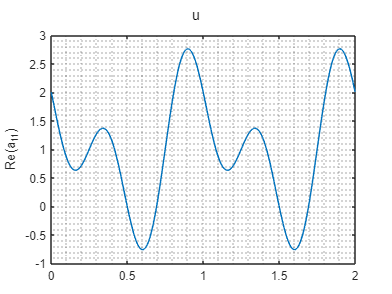

% u = 1 + cos - sin
figure
plot(u,1,0:0.01:2,title='u')


u.SinCosForm

ans = ans(:,:,1) =

    -1


ans(:,:,2) =

     0


ans(:,:,3) =

     1


ans(:,:,4) =

     1


ans(:,:,5) =

     0


u.ImagRealForm

ans = ans(:,:,1) =

    0.5000


ans(:,:,2) =

     0


ans(:,:,3) =

     1


ans(:,:,4) =

    0.5000


ans(:,:,5) =

     0


## Symbolic and sdpvar

The toolbox allows for definition of symbolic and sdp variable in the form of PhasorArray to perform all the previous operations

hP=5

hP = 5


%liste de sdp var servant aux phaseur 
P2=(sdpvar(size(A,1),size(A,2),hP,'symmetric','complex'))

Multi-dimensional SDPVAR object 2x2x5


%sdpvar phaseur 0 (réel)
P1=(ndsdpvar(size(A,1),size(A,2),1,'symmetric','real'))

Linear matrix variable 2x2 (symmetric, real, 3 variables)
Coeffiecient range: 1 to 1


%sdpvar phaseur array
P = PosPart2PhasorArray(P1,P2)

P =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 ndsdpvar]


PT=P.TB(h)

Linear matrix variable 22x22 (hermitian, complex, 33 variables)
Coeffiecient range: 1 to 1



%ou directement avec la methode statique de PhasorArray
P = PhasorArray.ndsdpvar(2,2,5,param='symmetric',real=true)

P =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 ndsdpvar]



P=sdpval(P)

P =   2×2×11 PhasorArray array with properties:

    Phasor3D: [2×2×11 double]


% P = value(value(P))
%to extract the value in P after optim

see LMI example for more details

## Lyapunov and Sylvester eq


$$\dot{M\left(t\right)} +A\left(t\right)\;M\left(t\right)+M\left(t\right)\;B\left(t\right)+C\left(t\right)=0,\textrm{periodic}$$


A=mreal(rand_phasor(4,4,7,"hurwitzeig",[-1 -0.7 -0.1 -0.3],"time_structure","hurwitz",output="PhasorArray"))

A =   4×4×15 PhasorArray array with properties:

    Phasor3D: [4×4×15 double]


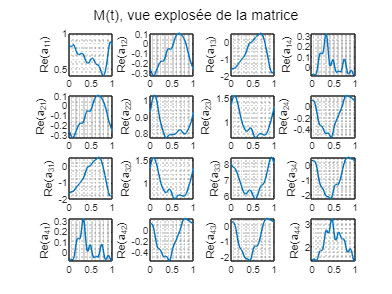

Q=PhasorArray(eye(4));

hp=10;
T0=1;

%A^TP + PA +Q =0
P=PhasorArray(Sylv_harmonique(A',A,Q,2*hp,2*pi/T0));
figure
plot(P)


nx=size(A,1)

nx = 4

nz=2

nz = 2


C=PhasorArray(rand_phasor(nz,nx,4,"time_structure","real"))

C =   2×4×9 PhasorArray array with properties:

    Phasor3D: [2×4×9 double]


O=rand(nz,nz)

O =     0.9018    0.3581
    0.4195    0.4890


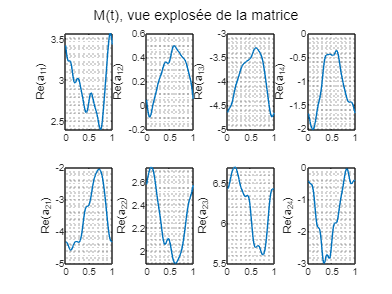


%dotM + -OM + MA -C =0
M=PhasorArray(Sylv_harmonique(-O,A,-C,2*hp,2*pi/T0));
plot(M)

## More...


% les formes fourier au lieu de Toepliz
A.TF_BT

ans =    0.1378 + 0.0364i   0.0067 - 0.0006i   0.0333 + 0.0536i  -0.4316 - 0.2218i
   0.0816 + 0.0100i   0.0277 + 0.0367i  -0.0714 + 0.0143i   0.0676 - 0.1966i
  -0.0234 + 0.0518i  -0.0274 - 0.0173i   0.0551 - 0.0094i  -0.0116 - 0.0443i
  -0.1859 - 0.0877i  -0.0249 - 0.0447i   0.0988 - 0.0096i  -0.7422 - 0.0932i
   0.0060 + 0.0302i  -0.0054 - 0.0231i  -0.0317 - 0.0274i   0.0006 + 0.0649i
   0.0144 - 0.0438i   0.0033 - 0.0029i   0.0131 + 0.0164i  -0.0772 + 0.0168i
  -0.0202 + 0.0109i  -0.0013 + 0.0045i  -0.0037 - 0.0197i   0.0150 + 0.0128i
  -0.0083 + 0.0388i  -0.0178 - 0.0165i  -0.0292 - 0.0356i   0.1385 + 0.0562i
   0.1569 - 0.2413i  -0.0007 + 0.0610i  -0.0317 + 0.0617i   0.2099 - 0.1827i
  -0.0059 + 0.1742i   0.0344 - 0.0328i  -0.0630 - 0.0362i  -0.0380 + 0.2365i


A.TF_TB 

ans =    0.1378 + 0.0364i   0.0067 - 0.0006i   0.0333 + 0.0536i  -0.4316 - 0.2218i
   0.0060 + 0.0302i  -0.0054 - 0.0231i  -0.0317 - 0.0274i   0.0006 + 0.0649i
   0.1569 - 0.2413i  -0.0007 + 0.0610i  -0.0317 + 0.0617i   0.2099 - 0.1827i
  -0.0772 - 0.0201i   0.0166 - 0.0228i   0.0161 + 0.0289i  -0.0707 + 0.0083i
   0.1188 + 0.1296i   0.0075 + 0.0096i  -0.1423 - 0.0132i  -0.0152 + 0.1408i
  -0.0836 + 0.2340i  -0.0255 - 0.0321i  -0.1085 - 0.1188i   0.1177 + 0.0585i
  -0.2610 - 0.1485i   0.1148 - 0.0209i   0.2137 - 0.2163i   0.0992 - 0.0519i
  -1.0237 + 0.0000i   0.0259 + 0.0000i   0.1280 + 0.0000i   0.0829 + 0.0000i
  -0.2610 + 0.1485i   0.1148 + 0.0209i   0.2137 + 0.2163i   0.0992 + 0.0519i
  -0.0836 - 0.2340i  -0.0255 + 0.0321i  -0.1085 + 0.1188i   0.1177 - 0.0585i




%forme Fourier vec en TB
A.FvTB(h)

ans =    0.1569 - 0.2413i
  -0.0772 - 0.0201i
   0.1188 + 0.1296i
  -0.0836 + 0.2340i
  -0.2610 - 0.1485i
  -1.0237 + 0.0000i
  -0.2610 + 0.1485i
  -0.0836 - 0.2340i
   0.1188 - 0.1296i
  -0.0772 + 0.0201i


A{:}.TF_BT

ans =    0.1378 + 0.0364i
   0.0816 + 0.0100i
  -0.0234 + 0.0518i
  -0.1859 - 0.0877i
   0.0067 - 0.0006i
   0.0277 + 0.0367i
  -0.0274 - 0.0173i
  -0.0249 - 0.0447i
   0.0333 + 0.0536i
  -0.0714 + 0.0143i



%TB2Array converti une matrice TB, dont on connait le nombre de bloc, pour
%en reconstruite le phasorArray 3D
TB2array(A.TB(h),size(A,1)) 

ans = ans(:,:,1) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,2) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,3) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,4) =

   0.137



sum(A,1)

ans =   1×4×15 PhasorArray array with properties:

    Phasor3D: [1×4×15 double]


permute(A,[2 1])

ans =   4×4×15 PhasorArray array with properties:

    Phasor3D: [4×4×15 double]


size(A,1)

ans = 4

size(A,2)

ans = 4

numel(A)

ans = 240

numelt(A)

ans = 16


angle=1.57 %rad

angle = 1.5700

evalp(A,angle)

ans =   -2.1349 + 0.0000i   0.1829 - 0.0000i   0.0503 + 0.0000i  -0.5951 + 0.0000i
   0.5171 + 0.0000i  -0.4907 - 0.0000i   0.0671 + 0.0000i   0.9822 + 0.0000i
  -0.9800 - 0.0000i   0.5906 + 0.0000i   0.7070 + 0.0000i   0.1833 - 0.0000i
  -0.5683 + 0.0000i   0.3015 - 0.0000i   0.5200 - 0.0000i  -1.5145 + 0.0000i



B=rand_phasor(3,1,7,'output','PhasorArray')

B =   3×1×15 PhasorArray array with properties:

    Phasor3D: [3×1×15 double]


iscolumn(B)

ans = logical
   1


isrow(B)

ans = logical
   0


isrow(B.')

ans = logical
   1


ismatrix(B)

ans = logical
   1


issquare(B)

ans = logical
   0



C=rand_phasor(1,1,8,'output','PhasorArray')

C =   1×1×17 PhasorArray array with properties:

    Phasor3D: [1×1×17 double]


isscalar(C)

ans = logical
   1



issquare(A)

ans = logical
   1


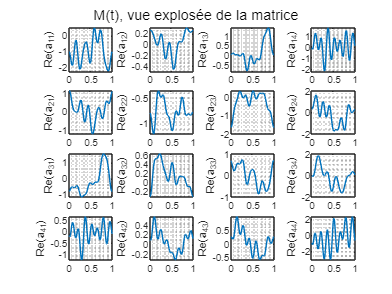


figure
plot(A)

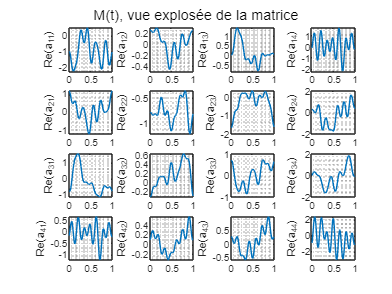

figure
plot(retro(A))